# Parameter estimation for the 2019-2020 oubreak of COVID-19

This file details how the methodology discussed in the article entitled *Parameter Estimation from ICC Curves* may be used to estimate parameters for COVID-19 case counts in the US. 

Author: Joceline Lega. Date created: 4/24/2020. Last modified: 7/23/2020

## Load cumulative data series and plot ICC curve

The ICC curve is obtained by smoothing and interpolating the reported cumulative data. In particular, it estimates missing incidence values and interpolates between data points to remove negative incidence reports, if any. The resulting time series is considered to be a more realistic estimate of the "true" evolution of the cumulative data. 

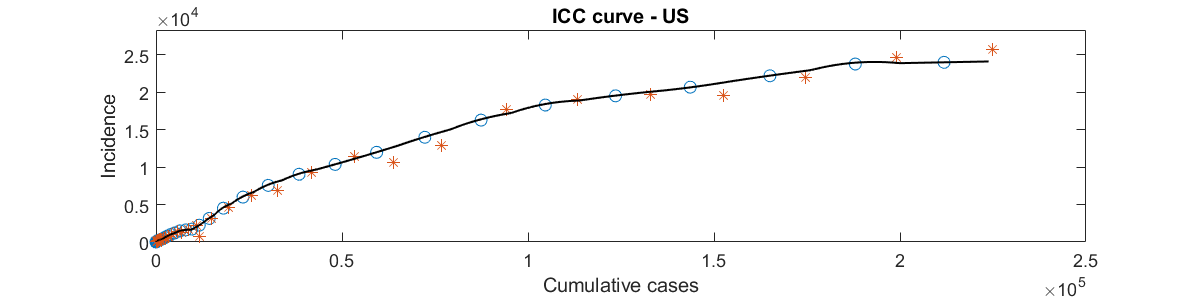

clear variables;
% Read data file
location_name='US'; time_unit='day';
dataset_date='6-19';
% dataset_date='4-27'; '5-17'; 
pathname=['../../covid_state_hosp_data_' dataset_date '/'];
% For JHU data, edit plot_ICC_curve.m
% Parameters
i_col=1;                % 1 for case count; 2 for deaths
i_end=0; smth_factor=6;
[~,C,I,C_raw,I_raw,C_raw0,I_raw0,C_ref,In_ref,DC,tme]=...
    plot_ICC_curve(location_name,pathname,smth_factor,i_end,i_col,1,...
    datenum('01/01/2020'),datenum('04/01/2020'));

d0=tme(1); disp(['First day of outbreak: ' datestr(d0)])

First day of outbreak: 07-Feb-2020


## Parameter values for different sizes of N

In `find_priors`, a range of values of $N,$ between the current number of cases and ten times as many is considered. Each value of $N$ is associated with optimal parameters $\beta$, $\gamma,$ and $z$ and the code identifies the vector of parameters $(\beta_{opt}, \gamma_{opt}, N_{opt}, z_{opt})$ which best fits the data (where best fit means minimum RMSE between ICC curve and the smoothed interpolated data). A range of values of $N$ around $N_{opt}$ for which the RMSE is within 2% of the RMSE for $N_{opt}$ is used to define a range of values for each of the parameters.

If the last argument of `find_priors` is set to 1, the ICC curve and the distribution of values of $R_0$ in the idetified parameter range are also plotted. The shape of the distribution of $R_0$ reflects the relationship between $N$ and $R_0$ for a fixed final number of cases associated with the outbreak.

Optimal ICC curve: N = 645469 - RMSE: 294.4016 - C_inf: 441224 - C_0 = 103.1539
Optimal ICC curve: beta = 0.5883 - gamma = 0.34959 - R_0 = 1.6828
Bounds for N: [467862, 1275364]
Bounds for R0: [1.2115, 3.175]
Bounds for beta: [0.3473, 1.3607]
Bounds for gamma: [0.10939, 1.1232]
Bounds for beta N: [162487.2126, 1735434.2217]


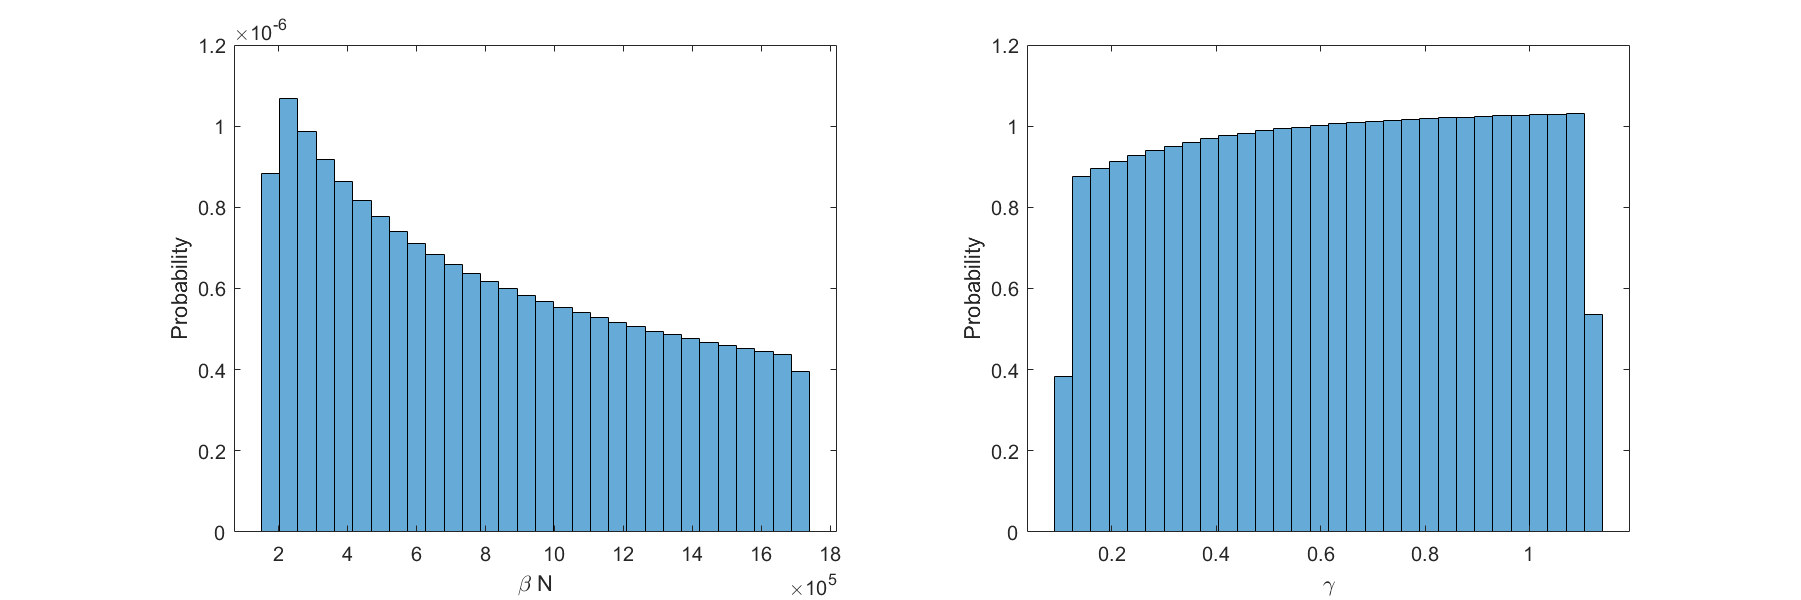

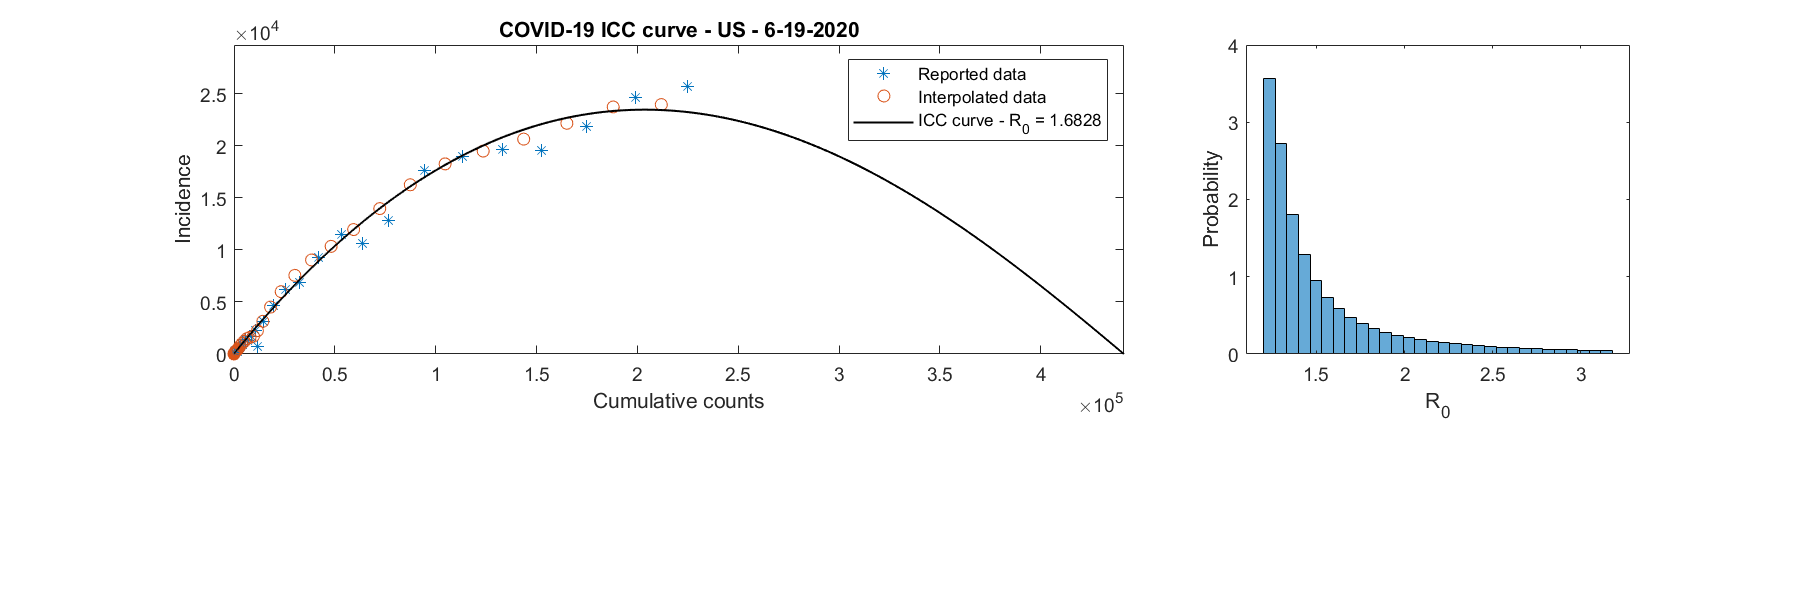

[X,bds]=find_priors(C,I,C_raw,I_raw,C_ref,DC,...
    [location_name ' - ' dataset_date '-2020'],1);

## Time course of the outbreak

Here, we plot the data (circles) and the predictions of the ICC curve (solid curves) for the optimal set of parameters. 

beta = 0.5883 - gamma = 0.34959 - R0 = 1.6828 - N = 645469


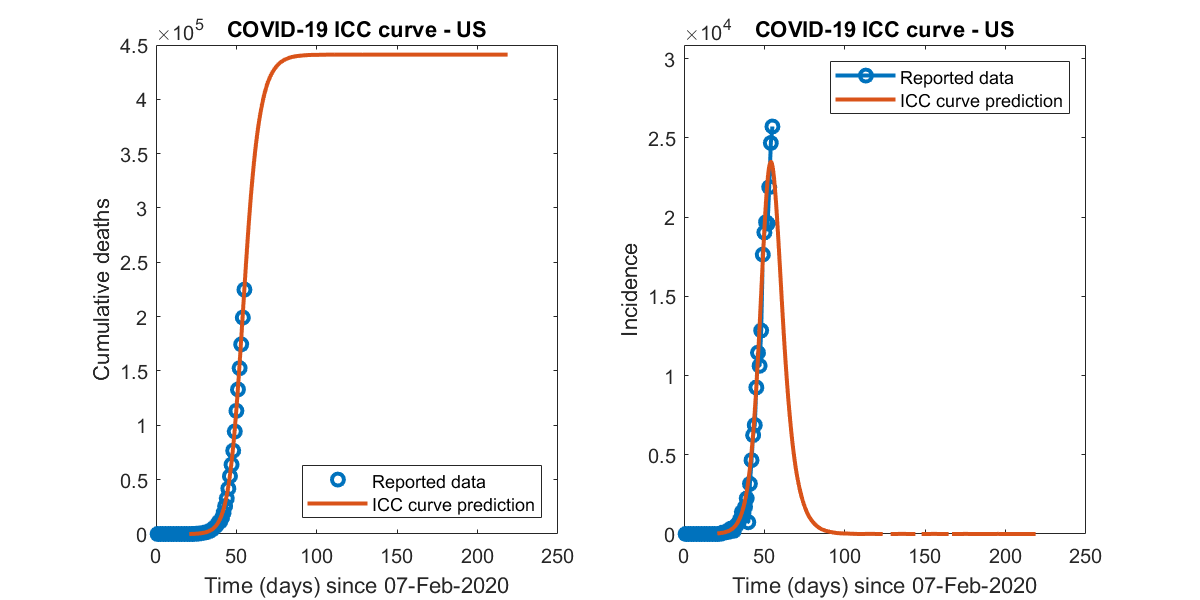

if ~isempty(X)
    disp(['beta = ' num2str(X(1)^2) ' - gamma = ' num2str(X(2)^2) ...
        ' - R0 = ' num2str((X(1)/X(2))^2) ' - N = ' num2str(round(X(3)))])
    plot_time_course(X,C,I,tme,C_raw0,I_raw0,d0,time_unit,location_name,2,1)
end

## Estimation of parameter ranges for all of the US states

The code `State_parameters.m` repeats the above process for all of the states listed in the file `list_of_states.csv`. In the event that no parameters are found for a dataset, the last data point is automatically removed and the fitting procedure is repeated, until parameter ranges for the ICC curve are obtained. The optimal parameters and their ranges are reported in an Excel output file (`outfile` in the code below). The number of points removed from the dataset appears in the last column of this file. Un-commenting and running the portion of code below would alter the Excel file created by `State_parameters`.

% % Read output file
% if i_col==1
%     outfile=['state_parameters_case_counts_' dataset_date '.xlsx'];
% else
%     outfile=['state_parameters_deaths.xlsx_' dataset_date '.xlsx'];
% end
% [~,txt,~]=xlsread(outfile);
% i_state=find(strcmp(txt(:,1),location_name));
% bds_w=[bds tme(1) tme(end) i_end];
% xlswrite(outfile,bds_w,1,['B' num2str(i_state)])